# ------------------ UVSPEC WRAPPER -----------------

% -----------------------------------------------------------


% This script will write .INP files using writeUVSPEC.m, run the created
% files using runUVSPEC/m, and then read the .OUT files using readUVSPEC.m.
% The intention of the script is to control the radiative transfer code
% UVSPEC from Matlab. The user will be able to create files, run them and
% view the results here in this live script


clear variables; close all;


% Created by Andrew J. Buggee

## DESIGNATE FOLDER, INPUT AND OUTPUT FILES

% for now, we will manually create uvspec.inp files, and simply call them
% out as variables

% folderName = ['/Users/andrewbuggee/Documents/CU-Boulder-ATOC/',...
%     'Hyperspectral-Cloud-Droplet-Retrieval-Research/LibRadTran/',...
%     'libRadtran-2.0.4/examples/'];


folderName = ['/Users/andrewbuggee/Documents/CU-Boulder-ATOC/Hyperspectral-Cloud-Droplet-Retrieval-Research/',...
    'LibRadTran/libRadtran-2.0.4/testing_UVSPEC/'];

% inputName = 'aerosolExample_withNewSSA.INP';
inputName = 'testing_singleScatterAlb.INP';
% inputName = 'UVSPEC_WC_MIE_2.INP';
% inputName = 'UVSPEC_RADIANCES.INP';
% inputName = 'UVSPEC_REPTRAN_SOLAR.INP';
% inputName = 'UVSPEC_REPTRAN_SOLAR_2.INP';
% inputName = 'TEST_EXAMPLE_1.INP';
% inputName = 'UVSPEC_REPTRAN_THERMAL.INP';
% inputName = {'TEST_EXAMPLE_0.INP','TEST_EXAMPLE_45.INP','TEST_EXAMPLE_75.INP'};
% inputName = 'UVSPEC_CLOUDCOVER_4.INP'; % run from 500-4000 nm

outputName = 'testing_singScatAlb';
% outputName = 'testing_UV_MIE.OUT';

% outputName = 'testingAerosol_singScatAlb.OUT';

% inputName = {'065_micronBand_droplets_4_microns_tau_1.INP','065_micronBand_droplets_4_microns_tau_5.INP',...
%     '065_micronBand_droplets_4_microns_tau_10.INP','065_micronBand_droplets_4_microns_tau_15.INP',...
%     '065_micronBand_droplets_4_microns_tau_20.INP','065_micronBand_droplets_4_microns_tau_25.INP',...
%     '065_micronBand_droplets_4_microns_tau_30.INP'};


% outputName = {'output_065_micronBand_droplets_4_microns_tau_1','output_065_micronBand_droplets_4_microns_tau_5',...
%     'output_065_micronBand_droplets_4_microns_tau_10','output_065_micronBand_droplets_4_microns_tau_15',...
%     'output_065_micronBand_droplets_4_microns_tau_20','output_065_micronBand_droplets_4_microns_tau_25',...
%     'output_065_micronBand_droplets_4_microns_tau_30'};




## RUN UVSPEC AND SAVE INPUTS/OUTPUTS



[inputSettings] = runUVSPEC(folderName,inputName,outputName);


if iscell(outputName)== true

    save([folderName,'GROUP_',outputName{1},'_settings.mat'],"inputSettings"); % save inputSettings to the same folder as the input and output file

else
    save([folderName,outputName,'_settings.mat'],"inputSettings"); % save inputSettings to the same folder as the input and output file
end




## READ UVSPEC OUTPUT FILES

if iscell(outputName)==true

    ds = cell(1,length(outputName));

    for jj = 1:length(outputName)

        [ds{jj},irrad_HU,rad_HU] = readUVSPEC(folderName,outputName{jj},inputSettings); % headers don't change per iteration

    end

else

    [ds,irrad_HU,rad_HU] = readUVSPEC(folderName,outputName,inputSettings);

end





## PLOT AND ANALYZE OUTPUT FILES

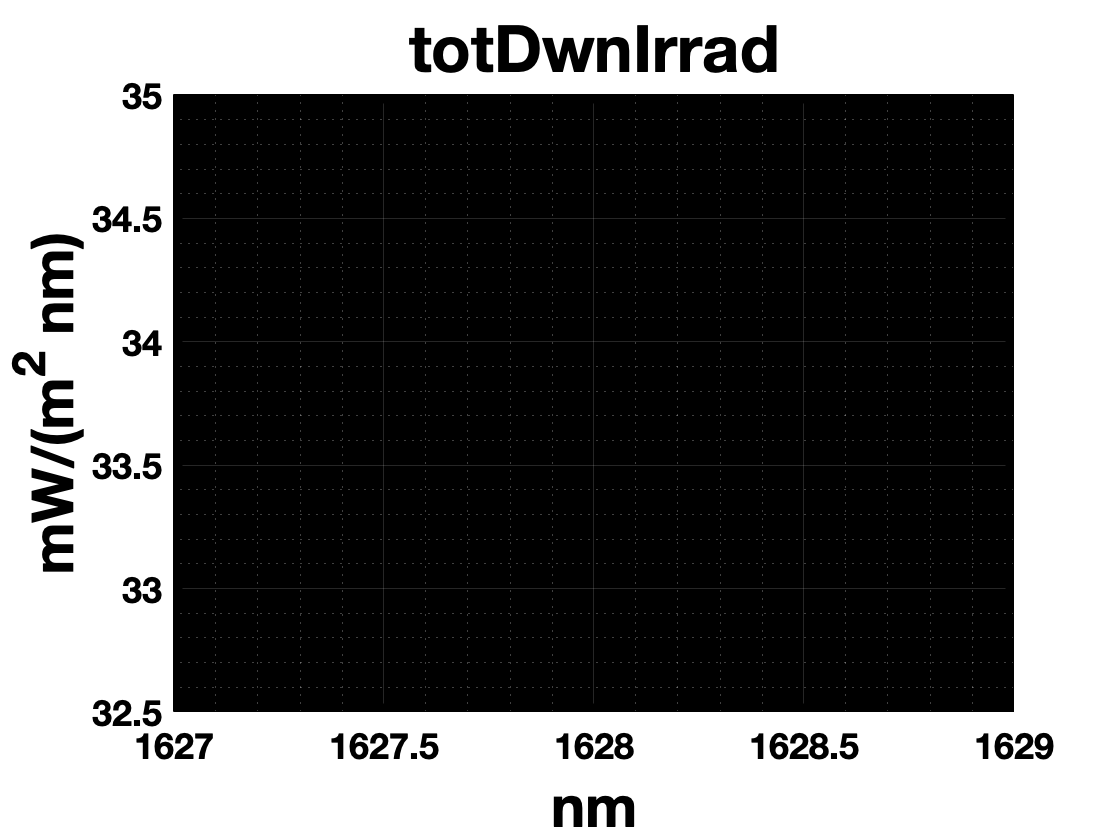

% If using the live script, always run these plot properties
liveScriptPlotting

% First lets plot the Irradiance Data
if iscell(ds)==false

    figure;
    p1 = plot(ds.wavelength,ds.irradiance.totDwnIrrad,'LineWidth',1);
    grid on; grid minor
    title(irrad_HU{1,8})
    xlabel(irrad_HU{2,1})
    ylabel(irrad_HU{2,2})
    %p1.Parent.Position(3) = 1; % this will make the subplots wider by 300 pixels
    % xlim([min(ds.wavelength) max(ds.wavelength)])

else
    % plot 3 irradiance curves

    index2plot = [1];

    figure;
    legendString = cell(1,length(index2plot));
    for ii = 1:length(index2plot)
        plot(ds{index2plot(ii)}.wavelength,ds{index2plot(ii)}.irradiance.totDwnIrrad,'LineWidth',1)
        hold on
        %         legendString{ii} = ds{index2plot(ii)}.irradiance.geometry;
    end

    grid on; grid minor
    title(irrad_HU{1,8})
    xlabel(irrad_HU{2,1})
    ylabel(irrad_HU{2,2})
    %p1.Parent.Position(3) = 1; % this will make the subplots wider by 300 pixels
    % xlim([min(ds.wavelength) max(ds.wavelength)])

end

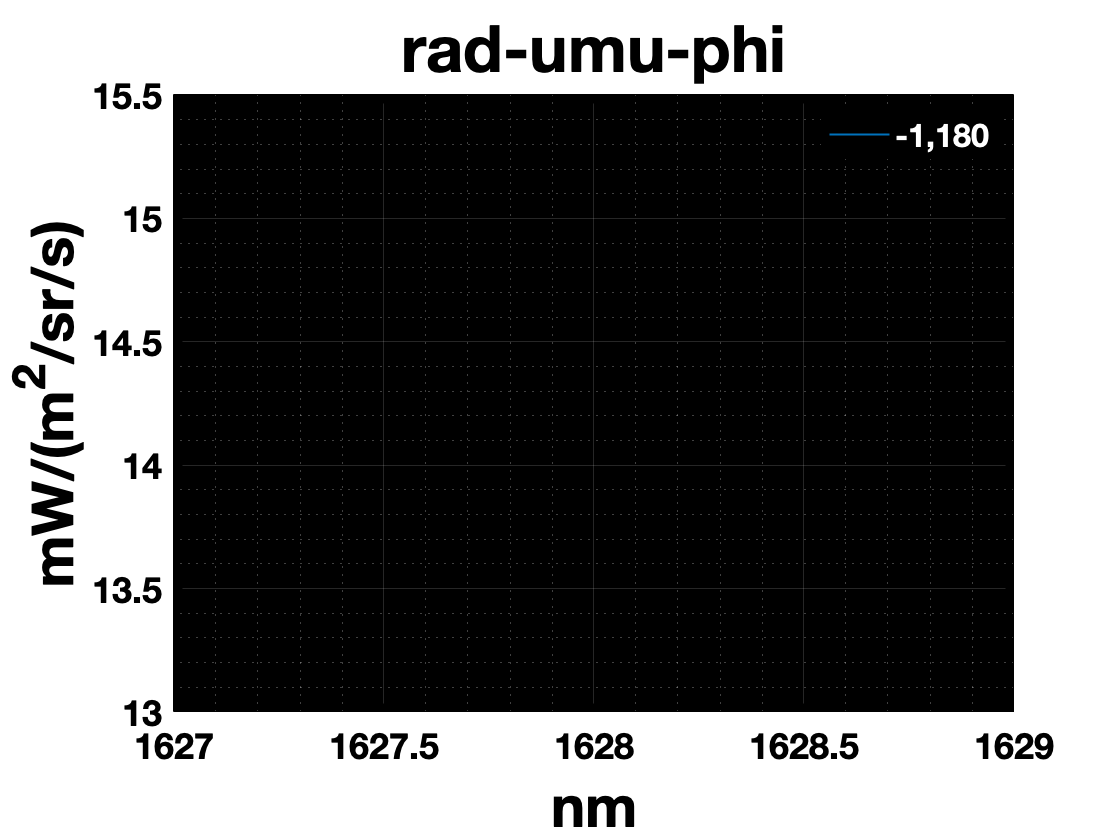


% Next lets plot the radiance data

% lets check and see how many geometry settings there are

geomSets = length(inputSettings{2,2})*length(inputSettings{2,3});

if geomSets <= 3

    if iscell(ds)==false

        figure;
        legendString = cell(1,geomSets);
        for ii = 1:geomSets
            plot(ds.wavelength,ds.radiance(ii).rad_umu_phi,'LineWidth',1)
            hold on
            legendString{ii} = ds.radiance(ii).umu_phi;
        end

        grid on; grid minor
        title(rad_HU{1,2})
        xlabel(irrad_HU{2,1})
        ylabel(rad_HU{2,2})
        legend(legendString,'TextColor','w')

    else

        figure;
        geom2Plot = 1;
        index2Plot = [1,4,7];

        changingVariable = [1,5:5:30]; % we assume if ds is a cell, you are changing a variable that must be changed from file to file. Enter the changing variable here
        legendString = cell(1,length(index2Plot));
        for ii = 1:length(index2Plot)
            plot(ds{index2Plot(ii)}.wavelength,ds{index2Plot(ii)}.radiance(geom2Plot).rad_umu_phi,'LineWidth',1)
            hold on
            legendString{ii} = num2str(changingVariable(index2Plot(ii)));
        end

        grid on; grid minor
        title(rad_HU{1,2})
        xlabel(irrad_HU{2,1})
        ylabel(rad_HU{2,2})
        legend(legendString,'TextColor','w')
    end

% more than 3 geometries, plot as many as you'd like!
elseif geomSets > 3

    if iscell(ds)==true % haven't made this work yet
        error('Havent made this code work yet!')
    end

    index2plot = [1,round(geomSets/2),geomSets];
    index2plot = [1,2,3,4,5,6];

    figure;
    sp1 = subplot(1,2,1);
    legendString = cell(1,length(index2plot));
    for ii = 1:length(index2plot)
        plot(ds.wavelength,ds.radiance(index2plot(ii)).rad_umu_phi,'LineWidth',1)
        hold on
        legendString{ii} = ds.radiance(index2plot(ii)).umu_phi;
    end

    sp1.Parent.Position(3) = sp1.Parent.Position(3)+300; % this will make the subplots wider by 300 pixels
    grid on; grid minor
    title(rad_HU{1,2})
    xlabel(irrad_HU{2,1})
    ylabel(rad_HU{2,2})
    legend(legendString,'TextColor','w')

    r = 1;
    sp2 = subplot(1,2,2);
    % Plot the position of the sun
    polarplot(pi/180*inputSettings{2,5},r*sind(inputSettings{2,4}),'*','MarkerSize',15,'Color',[0.9290, 0.6940, 0.1250])
    hold on
    set(gca,'ColorOrderIndex',1)
    for ii = 1:length(index2plot)
        geom = str2num(ds.radiance(index2plot(ii)).umu_phi); %#ok<ST2NM> % first value is umu, second is azimuth
        sinT = sqrt(1 - geom(1).^2);

        polarplot(pi/180*geom(2),r*sinT,'.','MarkerSize',12)
        hold on
    end
    set(gca,'FontSize',14)
    title('Geometry of Sun and Looks','FontSize',20)

else

    index2plot = [1,round(geomSets/2),geomSets];


    figure;
    sp1 = subplot(1,2,1);
    legendString = cell(1,length(index2plot));
    for ii = 1:length(index2plot)
        plot(ds.wavelength,ds.radiance(index2plot(ii)).rad_umu_phi,'LineWidth',1)
        hold on
        legendString{ii} = ds.radiance(index2plot(ii)+1).umu_phi;
    end

    sp1.Parent.Position(3) = sp1.Parent.Position(3)+300; % this will make the subplots wider by 300 pixels
    grid on; grid minor
    title(rad_HU{1,2})
    xlabel(irrad_HU{2,1})
    ylabel(rad_HU{2,2})
    legend(legendString,'TextColor','w','Location',"best")

    r = 1;
    sp2 = subplot(1,2,2);
    % Plot the position of the sun
    polarplot(pi/180*inputSettings{2,5},r*sind(inputSettings{2,4}),'*','MarkerSize',15,'Color',[0.9290, 0.6940, 0.1250])
    hold on
    set(gca,'ColorOrderIndex',1)
    for ii = 1:length(index2plot)
        geom = str2num(ds.radiance(index2plot(ii)).umu_phi); %#ok<ST2NM> % first value is umu, second is azimuth
        sinT = sqrt(1 - geom(1).^2);

        polarplot(pi/180*geom(2),r*sinT,'.','MarkerSize',12)
        hold on
    end
    set(gca,'FontSize',14)
    title('Geometry of Sun and Looks','FontSize',20)



end